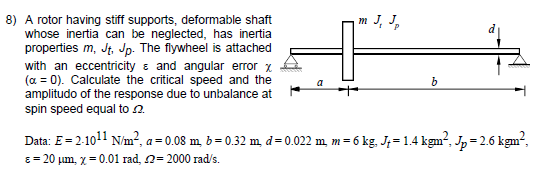

clear all
clc 

E=2e11;
a=.08;
b=.32;
d=.022;
m=6;
Jt=1.4;
Jp=2.6;
ecc=20e-6;
x=.01;
w=2000;

I=pi*d^4/64;
L=a+b;
delta=(Jp-Jt)/m;
K=3*E*I*L/(a*b)*[(L^2-3*a*L+3*a^2)/(a*b)^2  (2*a-L)/(a*b)
                 (2*a-L)/(a*b)              1];
             
wcr1=1/sqrt(2*m)*sqrt(K(1,1)-K(2,2)/delta+sqrt((K(1,1)+K(2,2)/delta)^2-4*K(1,2)^2/delta));

disp('Bending critical speed [rad/s] = ')
disp(wcr1)
disp(' ')

del=-m*(Jp-Jt)*w^4+(K(1,1)*(Jp-Jt)+m*K(2,2))*w^2+K(1,1)*K(2,2)-K(1,2)^2;

% Static unbalace
z0e=m*ecc*w^2*((Jp-Jt)*w^2+K(2,2))/del;
phi0e=-m*ecc*w^2*K(1,2)/del;

% Couple unbalace
z0x=x*w^2*(Jp-Jt)*K(1,2)/del;
phi0x=x*w^2*(Jp-Jt)*(m*w^2-K(1,1))/del;

disp(' Diplacement amplitude due to static unbalace [m] = ')
disp(z0e)
disp(' ')
disp(' Rotation amplitude due to static unbalace [rad] = ')
disp(phi0e)
disp(' ')
disp(' Diplacement amplitude due to couple unbalace [m] = ')
disp(z0x)
disp(' ')
disp(' Rotation amplitude due to couple unbalace [rad] = ')
disp(phi0x)
disp(' ')